clear all
close all

% Define Drag Coefficient Regression:
global cd_mdl
%Variables: [angle_alpha, angle_beta, angle_gamma, num_cars]
%Solutiuon: [Coefficient of Drag]
var = [15,30,10,3;15,15,10,3;50,30,20,3;15,50,20,3;15,15,10,7;30,50,10,15;15,15,20,7;15,30,10,15;50,50,10,3;30,15,20,3;50,30,20,7;15,15,20,3]; 
sol = [0.7306;0.49511;0.603478;0.865479;0.825286;1.33042;0.7927;1.16979;0.869678;0.51569;1.02362;0.438809];
cd_mdl=fitlm(var,sol);

%%% Set lower and upper bounds
%lower and upper bounds for train optimization
lb_network = [1,1,1,1,1,1,1,1,1,1,1,1];
ub_network = [133,307,133,307,133,307,133,307,133,307,133,307];

%lower and upper bounds for train optimization
lb_train =[15,15,10,3];
ub_train =[50,50,20,15];

%lower and upper bounds for safety optimization
lb_safety = [0 0 0 0 25];
ub_safety = [5000000000 1 60 200 100];

%Set overall lower and upper bounds
lb_total = [lb_network, lb_train, lb_safety] 

lb_total =      1     1     1     1     1     1     1     1     1     1     1     1    15    15    10     3     0     0     0     0    25


ub_total = [ub_network, ub_train, ub_safety]

ub_total = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000



Single objective optimization:
21 Variables
13 Integer variables
33 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240         0.03295          0.4535        0
    2              360         0.01966          0.2566        0
    3              480         0.01966          0.1578        1
    4              600         0.01285          0.1535        0
    5              720         0.01127         0.09597        0
    6              840         0.01062          0.0891        0
ga stopped because the average change in the penalty function value is less than options.FunctionTolerance but 
constraints are not satisfied to within options.ConstraintTolerance.


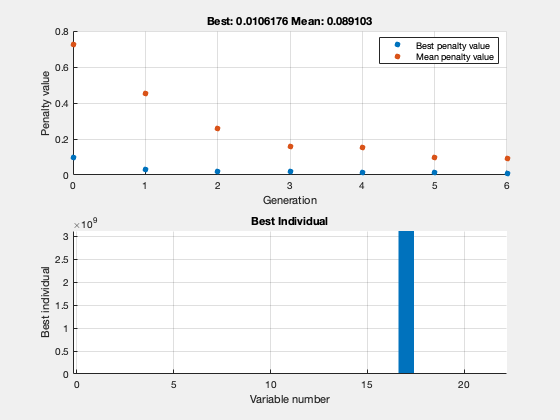

%%% Set GA parameters
lb = lb_total;
ub = ub_total;
intcon = [1,2,3,4,5,6,7,8,9,10,11,12,16]; 
nvars = 21;
nonlincon = @combinedNonlincon;
fun = @costObj;

options = optimoptions('ga', ...
    'Display', 'iter', ...                          
    'PlotFcn', {@gaplotbestf, @gaplotbestindiv}, ... 
    'UseParallel', false, ...                        % switched to false
    'PopulationSize', 120, ...
    'EliteCount', ceil(0.15 * 120), ...             % 15% of population kept as elite
    'CrossoverFraction', 0.70, ...                   % 70% of population undergoes crossover
    'CrossoverFcn', @crossoverlaplace, ...          % good for real-valued obj funcs
    'MutationFcn', @mutationpower, ...      % adaptive mutation but only in the feasible space
    'SelectionFcn', @selectiontournament, ...       % tournament selection
    'MaxGenerations', 50, ...
    'FunctionTolerance', 1e-2, ...                  % stop if improvement in func value is very small
    'ConstraintTolerance', 1e-6, ...                % tight, but not zero, tolerance on constraints -->changed from 1e-3 to 0
    'InitialPenalty', 5, ...
    'PenaltyFactor', 100, ...                       % quickly increase penalties for violating constraints
    'MaxStallGenerations', 5);                     % stop if no improvement (beyond tolerance) after 20 generations
%Run GA
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);

%calculate individual scores
convenience_score = networkScore(x_star(1:12))

convenience_score = single
0.5015

train_veloc = TrainVelocity(predict(cd_mdl,x_star(13:16)))

train_veloc = 69.4615

number_of_accidents = accident_count_function(x_star(16:21))

number_of_accidents = 44.8356


fval_individual = [convenience_score, train_veloc, number_of_accidents];

%calculate individual costs
network_cost = networkCost(x_star(1:12))

network_cost = single
534572000

train_cost = TrainCost(x_star(16))

train_cost = 70000000

safety_cost = safety_system_cost_function(x_star(17:21))

safety_cost = 4.7955e+08

costs_individual = [network_cost, train_cost, safety_cost]

costs_individual = 1×3 single row vector
   534572000    70000000   479554336
